Matlab code for the Course: **Modelling and Simulation Mechatronics System (2020)**

by Enrico Bertolazzi and Francesco Biral

Dipartimento di Ingegneria Industriale

Università degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

#### Initialize by cleaning memory and widows

 close all;

#### Initialize parameters of the model and instantiate model class

mass    = 1;
gravity = 9.81;
ell     = 1;
Iz      = 1;
DAE     = BiralDAE1( mass, gravity, ell, Iz );

#### Initialize the solver class

solver = DAE3TaylorSolver();
solver.setDAE( DAE );

#### Initialize the range where solution is computed and initial conditions

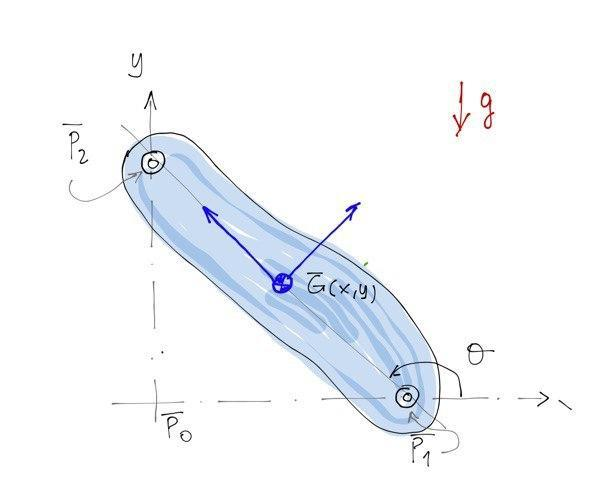

T     = 10;
DT    = 0.1;
theta = pi/4;
x     = -ell*sin(theta)/2;
y     = ell*cos(theta)/2;
% x, y, theta
p0    = [ x, y, theta ];
omega = 0.1;
u     = -ell*cos(theta)*omega/2;
v     = -ell*sin(theta)*omega/2;
% u, v, omega
v0    = [ u, v, omega ];

#### Advance the DAE (using not stabilized index-1 DAE)

tt  = 0:DT:T;
tt1 = 0:DT/10:T;
tt2 = 0:DT/100:T;
[p, v ] = solver.advance_simple( tt,  p0, v0 );
[p1,v1] = solver.advance_simple( tt1, p0, v0 );
[p2,v2] = solver.advance_simple( tt2, p0, v0 );

#### Position of center of gravity

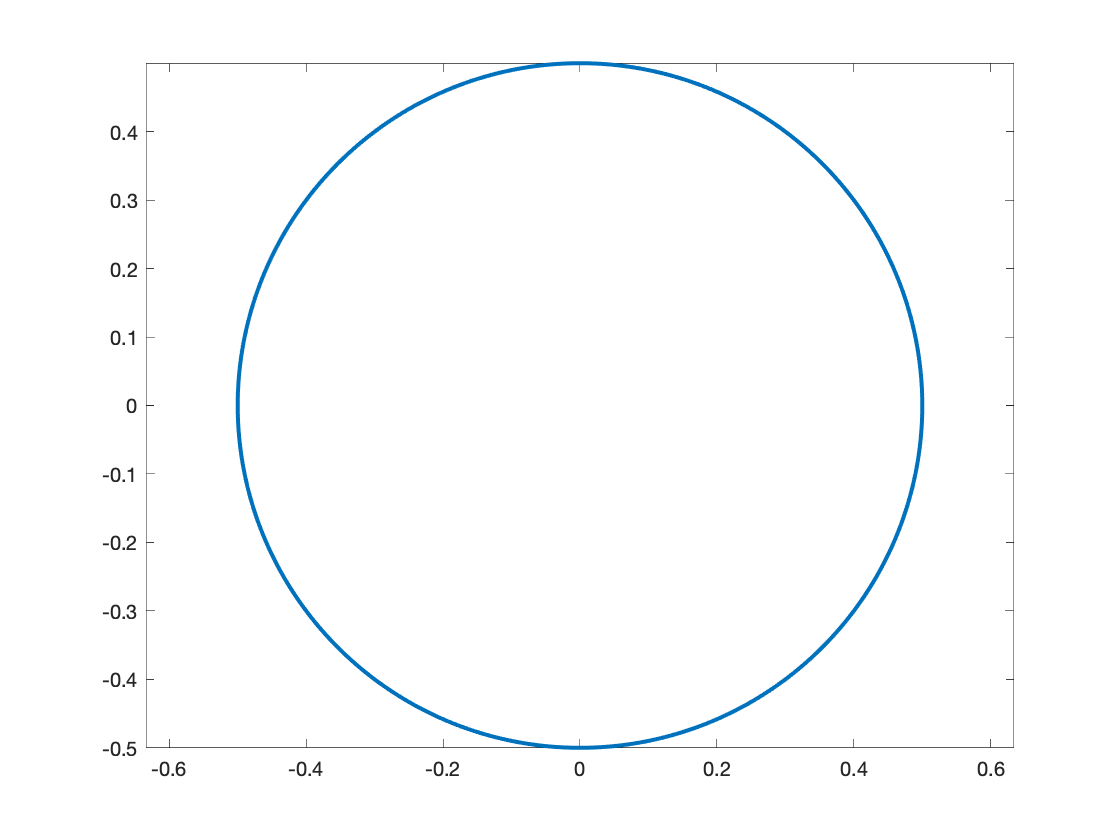

thg = pi:0.01:4*pi;
xg  = -ell*sin(thg)/2;
yg  = ell*cos(thg)/2;
hold off
plot(xg,yg,'LineWidth',2);
axis equal;

#### plot solution

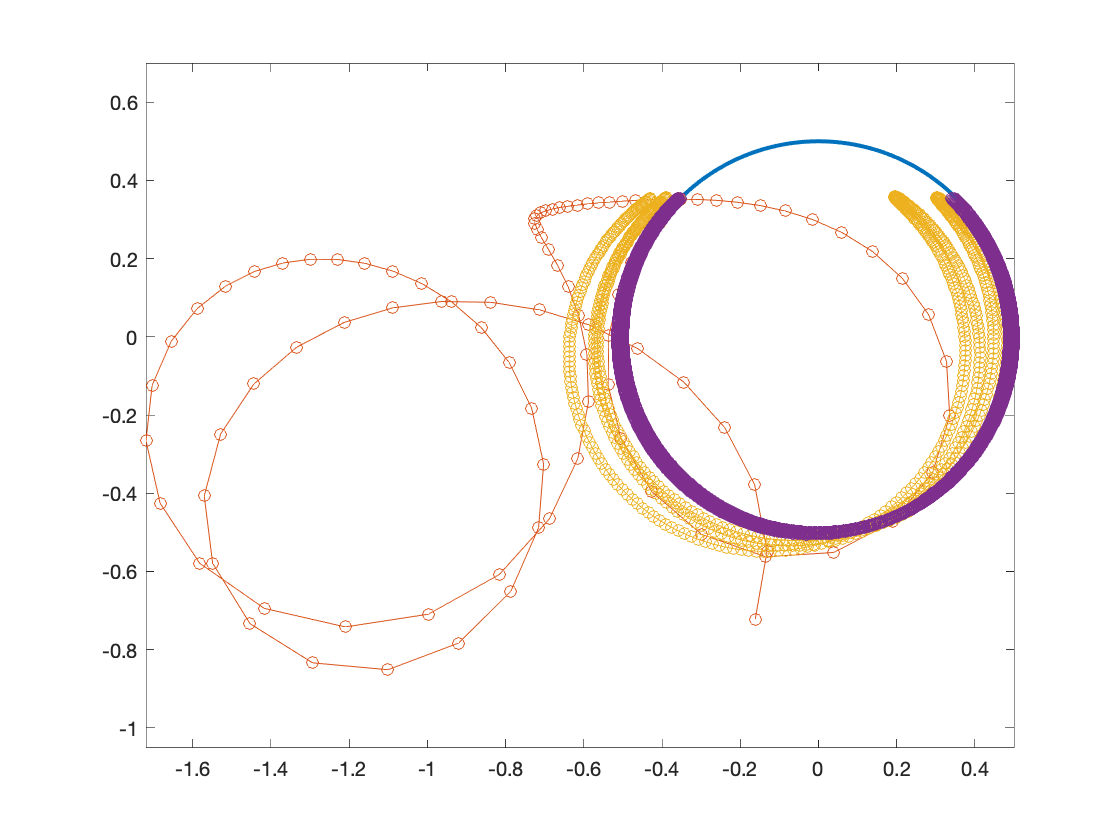

figure();
plot( xg, yg, 'Linewidth', 2);
hold on;
plot( p(1,:),  p(2,:),  'o-', 'Linewidth', 0.2);
plot( p1(1,:), p1(2,:), 'o-', 'Linewidth', 0.2);
plot( p2(1,:), p2(2,:), 'o-', 'Linewidth', 0.2);
hold off
axis equal

#### Plot animation

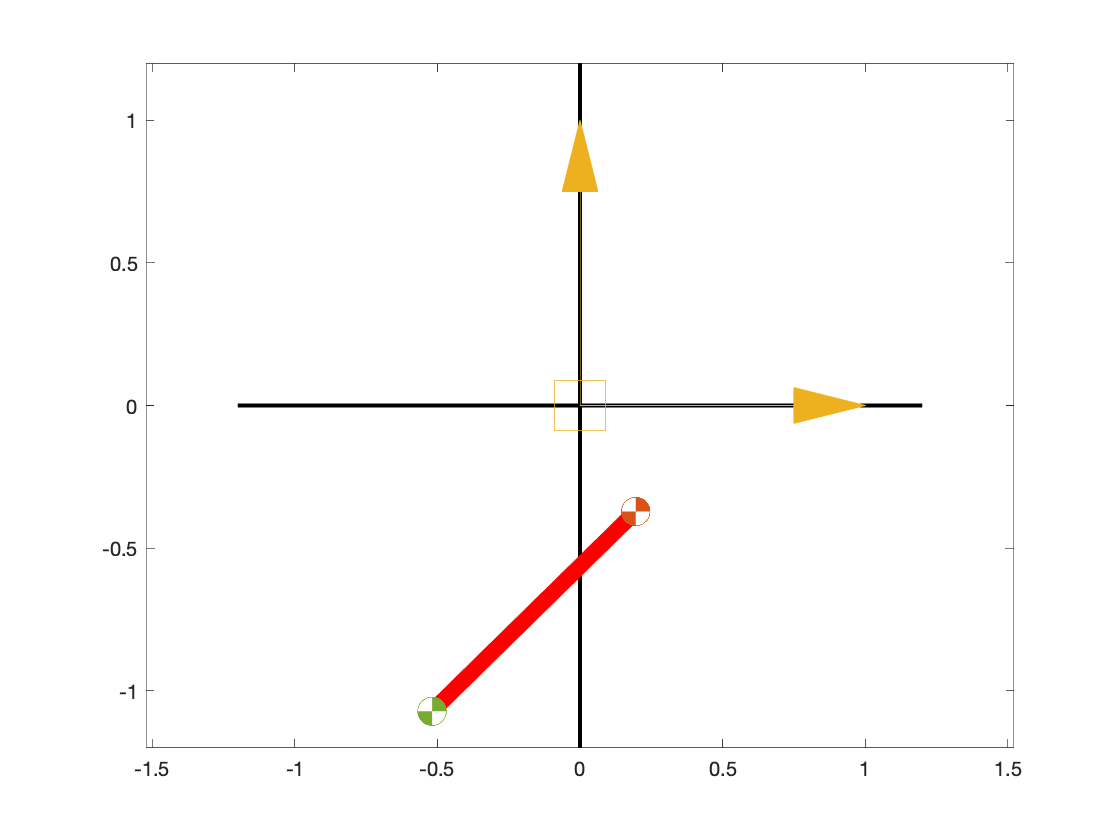

figure();
for k=1:size(p,2)
  DAE.plot(p(:,k));
  axis equal
  drawnow;
end

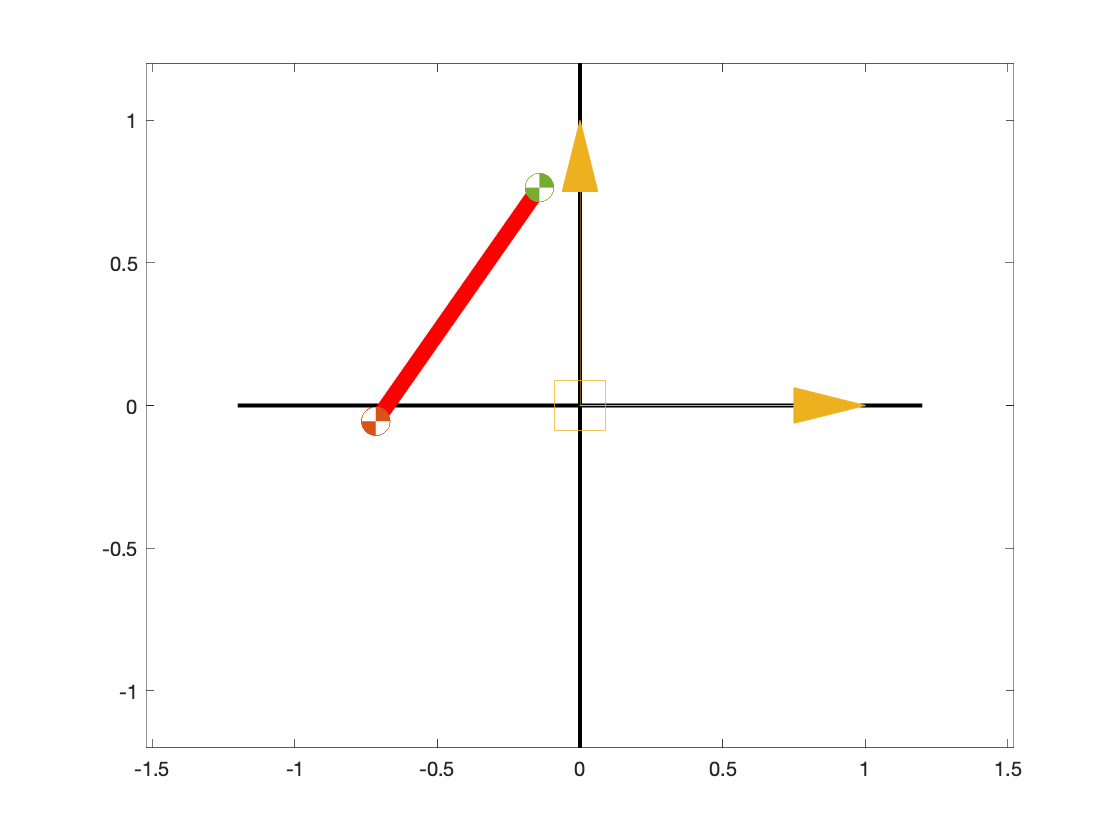

figure();
for k=1:10:size(p1,2)
  DAE.plot(p1(:,k));
  axis equal
  drawnow;
end

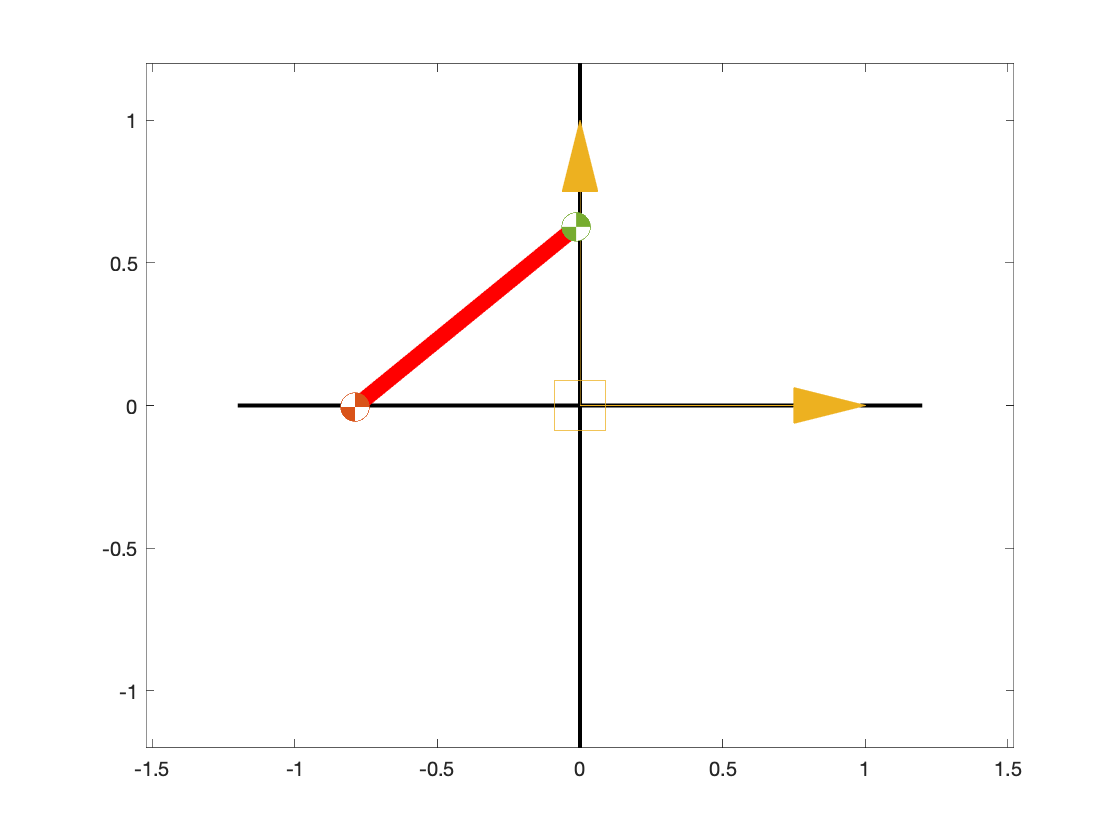

figure();
for k=1:100:size(p2,2)
  DAE.plot(p2(:,k));
  axis equal
  drawnow;
end

#### Advance the DAE (using stabilized index-1 DAE)

choose the parameters

eta   = 0.5;
omega = 10;

advance

tt  = 0:DT:T;
tt1 = 0:DT/10:T;
tt2 = 0:DT/100:T;
[ps, vs ] = solver.advance_Baumgarte( tt,  p0, v0, eta, omega );
[ps1,vs1] = solver.advance_Baumgarte( tt1, p0, v0, eta, omega );
[ps2,vs2] = solver.advance_Baumgarte( tt2, p0, v0, eta, omega );

#### plot solution

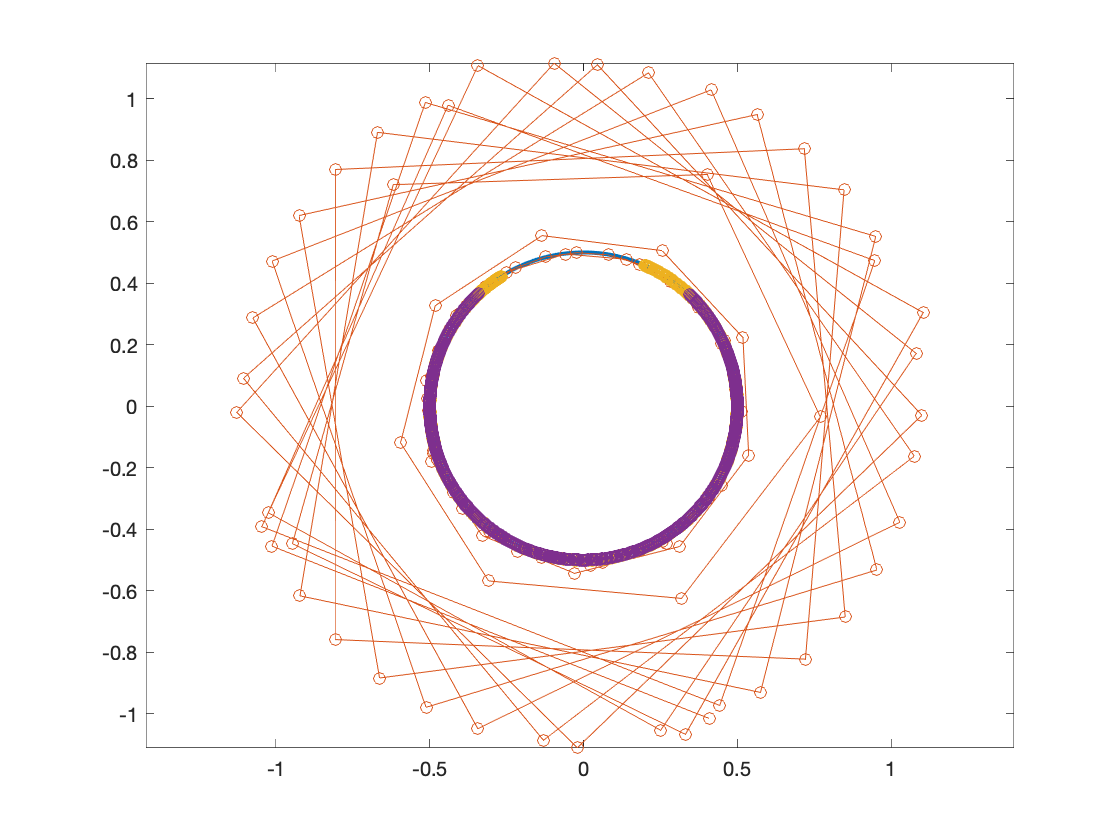

figure();
plot( xg, yg, 'Linewidth', 2);
hold on;
plot( ps(1,:),  ps(2,:),  'o-', 'Linewidth', 0.2);
plot( ps1(1,:), ps1(2,:), 'o-', 'Linewidth', 0.2);
plot( ps2(1,:), ps2(2,:), 'o-', 'Linewidth', 0.2);
hold off
axis equal

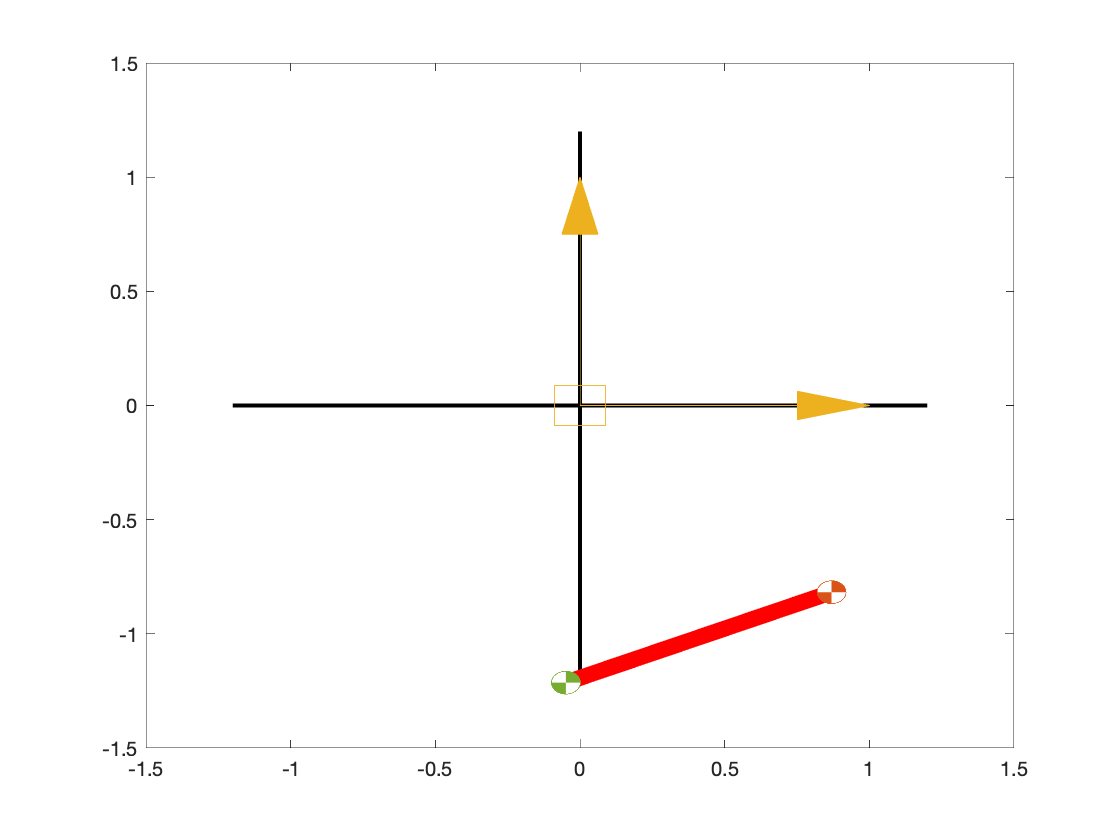

figure();
for k=1:size(ps,2)
  DAE.plot(ps(:,k));
  drawnow;
end

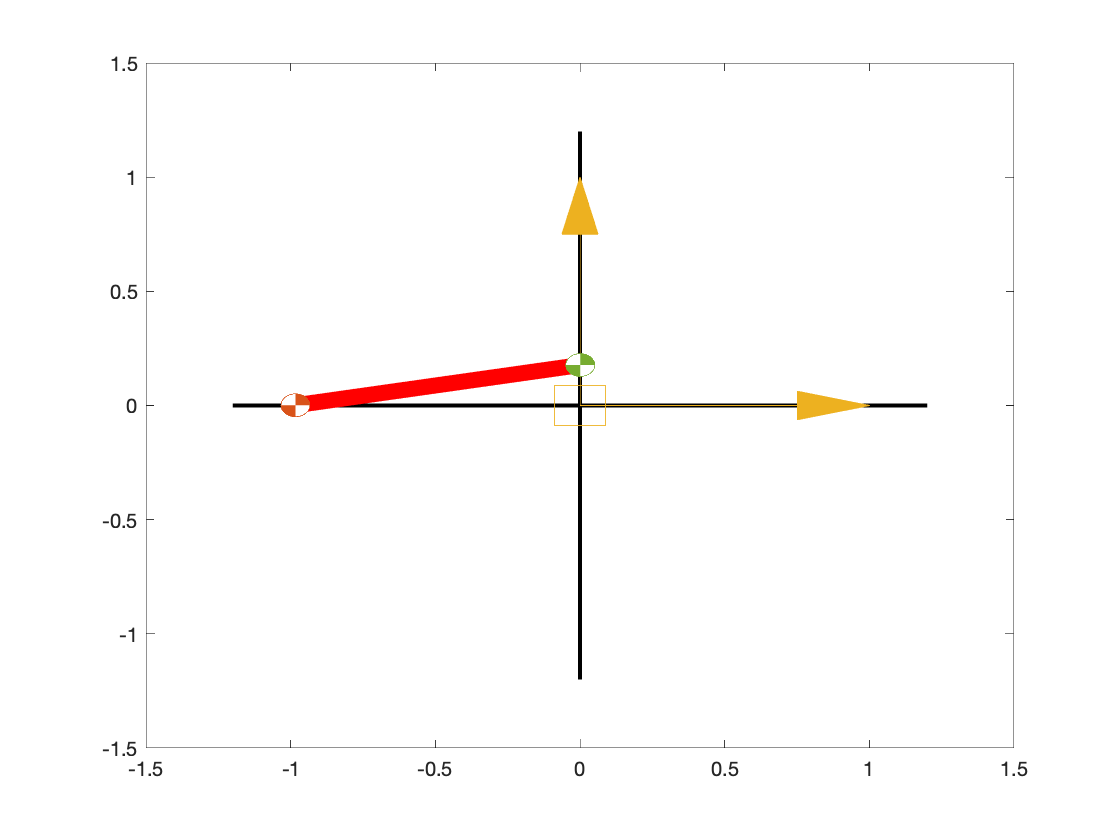

figure();
for k=1:10:size(ps1,2)
  DAE.plot(ps1(:,k));
  drawnow;
end

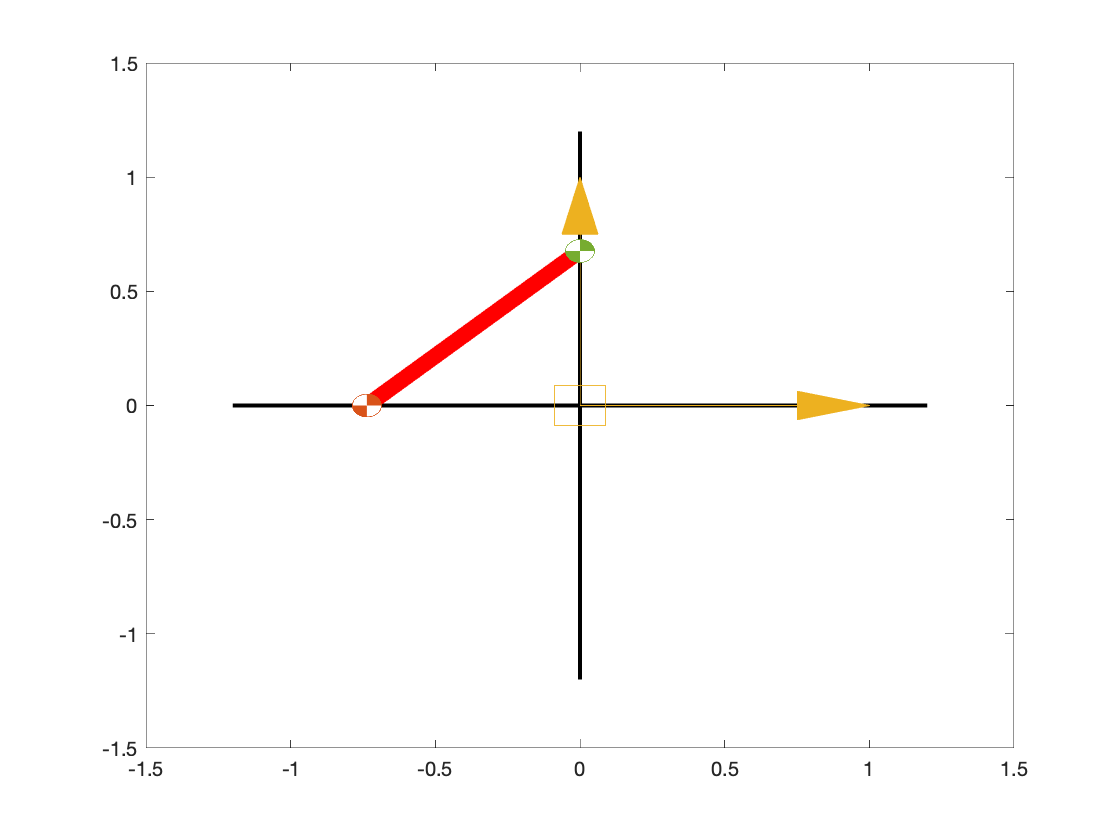

figure();
for k=1:100:size(ps2,2)
  DAE.plot(ps2(:,k));
  drawnow;
end

#### Advance the DAE (using stabilized projection)

#### Initialize the solver class

RK_1 = ImplicitEuler();
RK_2 = Heun();
RK_3 = RK4();
psolver = DAE3ProjectionSolver();
psolver.setDAE( DAE );


advance

tt = 0:DT:T;
psolver.setRK( RK_1 );
[ps_1, vs_1] = psolver.advance( tt, p0, v0 );
psolver.setRK( RK_2 );
[ps_2, vs_2] = psolver.advance( tt, p0, v0 );
psolver.setRK( RK_3 );
[ps_3, vs_3] = psolver.advance( tt, p0, v0 );

#### plot solution

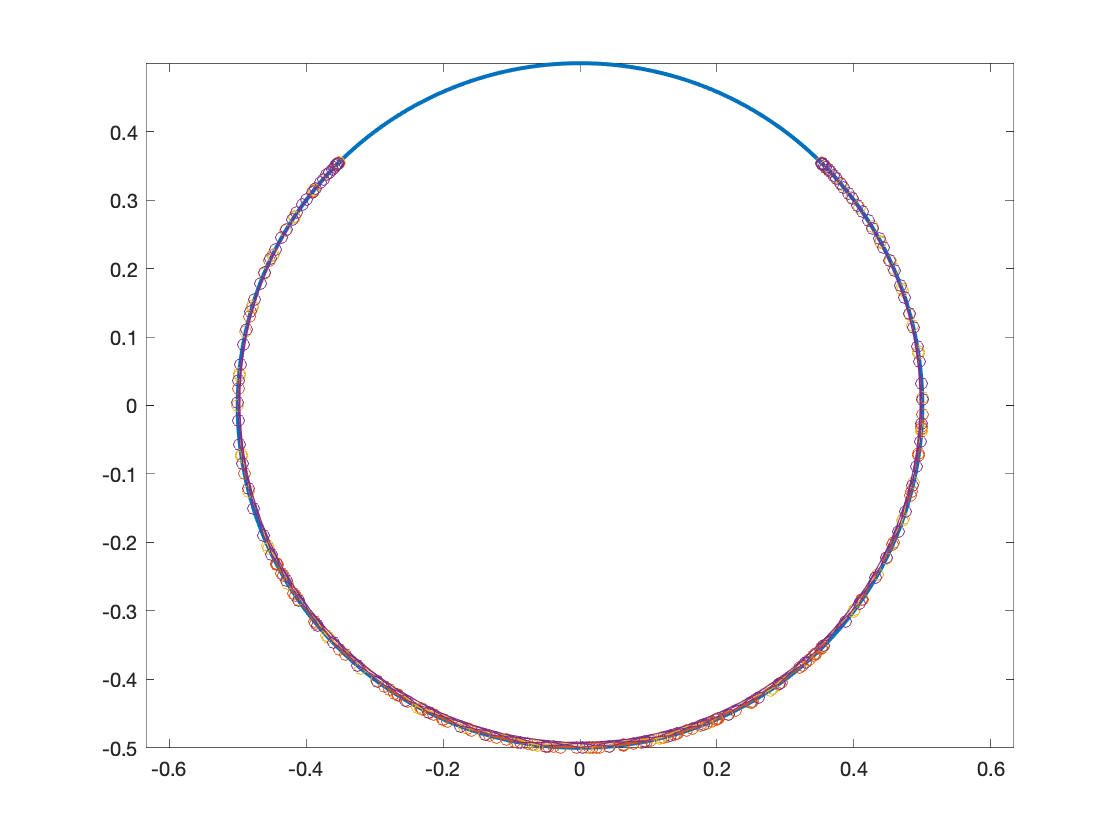

figure();
plot( xg, yg, 'Linewidth', 2);
hold on;
plot( ps_1(1,:), ps_1(2,:), 'o-', 'Linewidth', 0.2);
plot( ps_2(1,:), ps_2(2,:), 'o-', 'Linewidth', 0.2);
plot( ps_3(1,:), ps_3(2,:), 'o-', 'Linewidth', 0.2);
hold off
axis equal

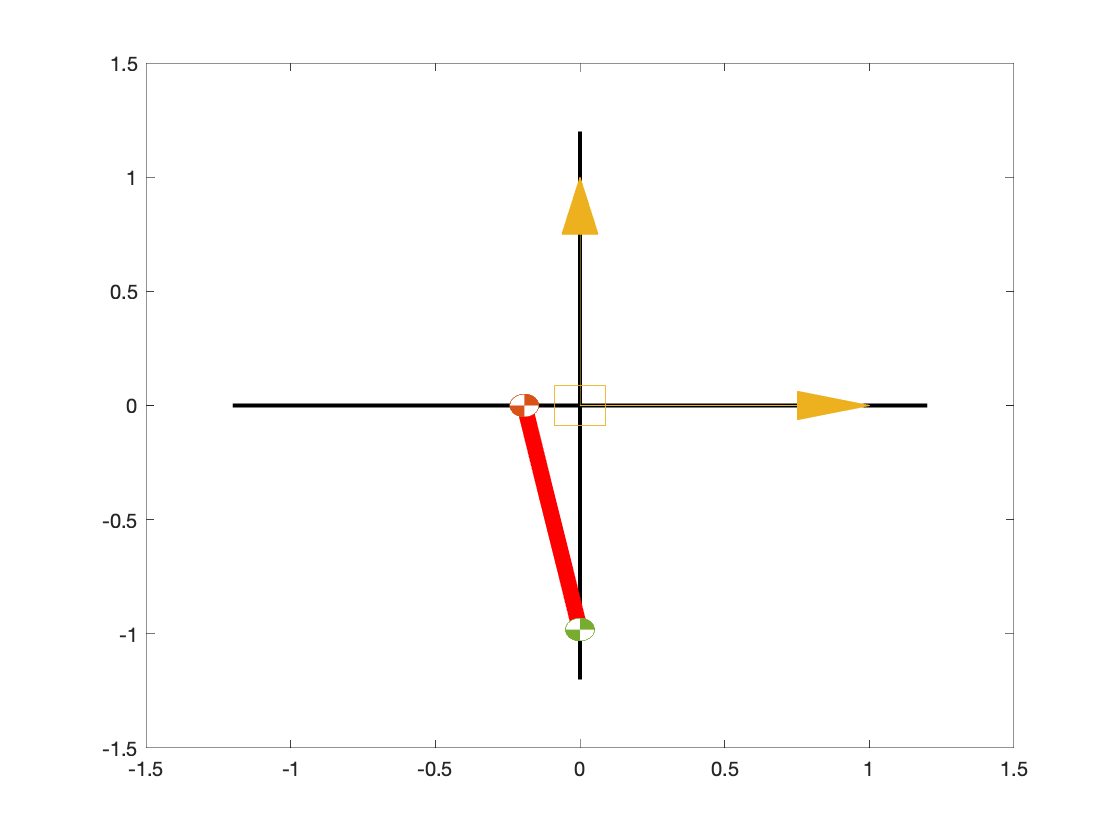

figure();
for k=1:size(ps_1,2)
  DAE.plot(ps_1(:,k));
  drawnow;
end

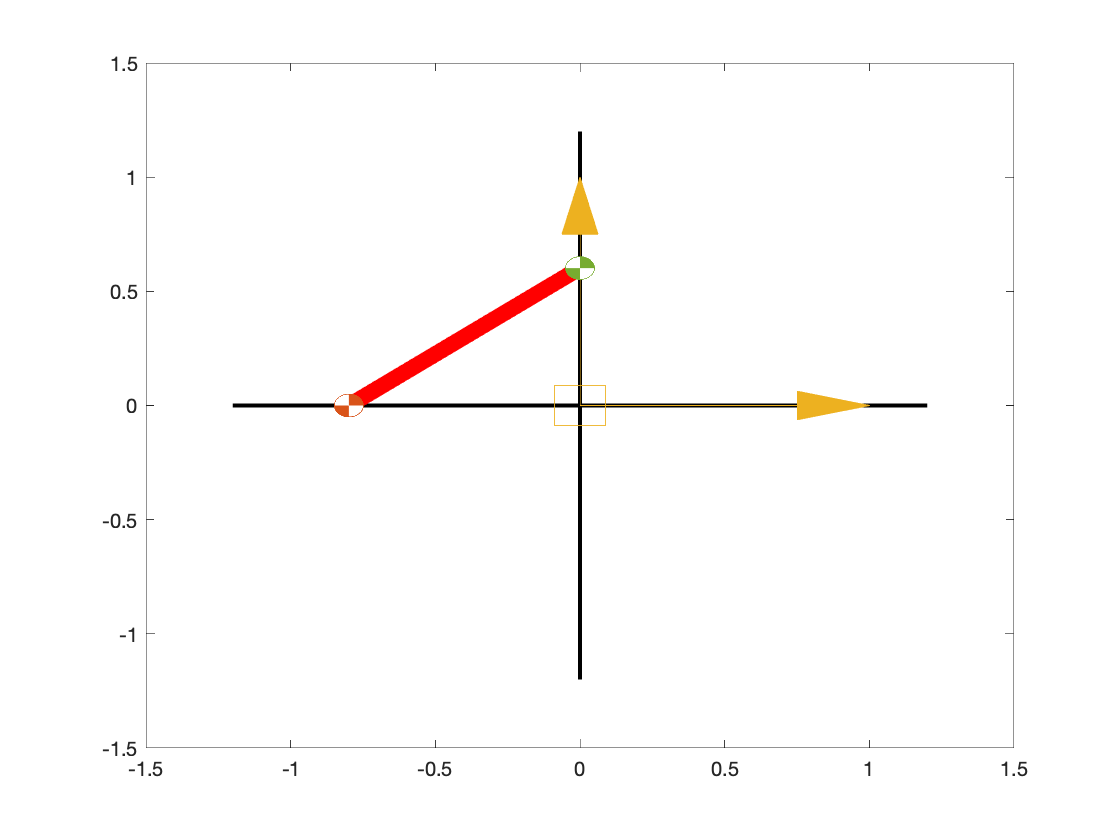

figure();
for k=1:size(ps_2,2)
  DAE.plot(ps_2(:,k));
  drawnow;
end

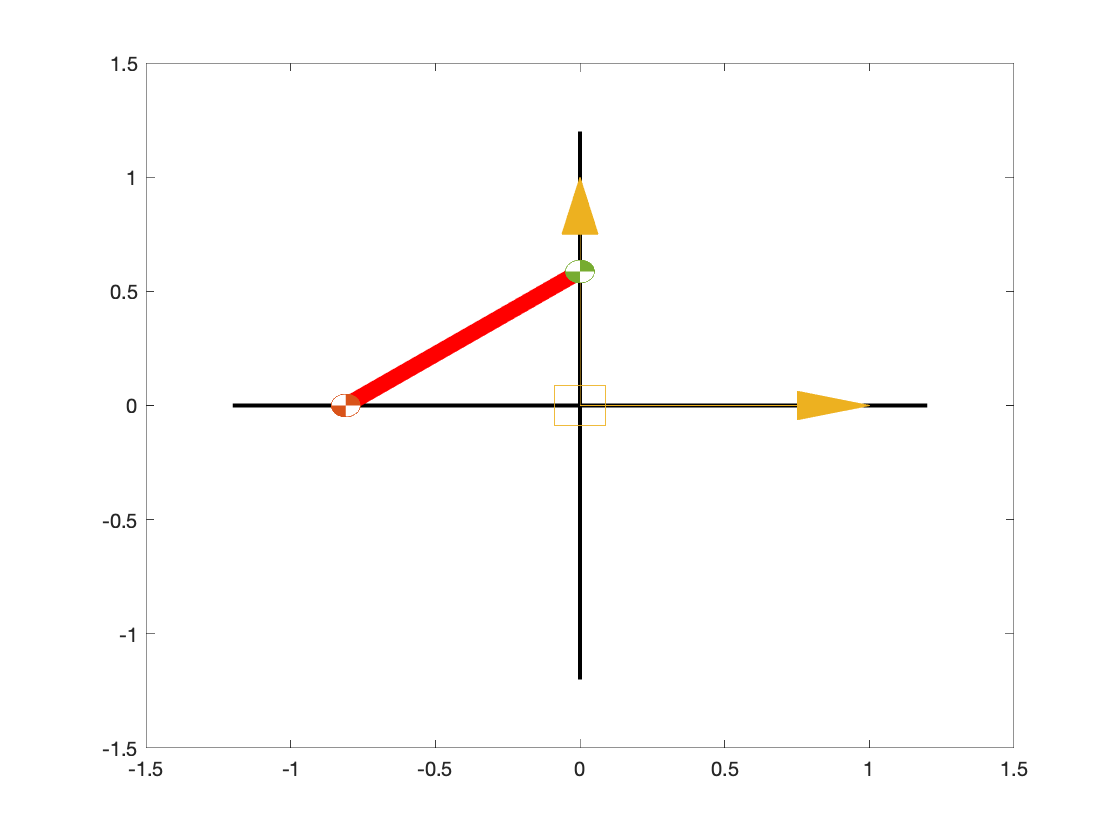

figure();
for k=1:size(ps_3,2)
  DAE.plot(ps_3(:,k));
  drawnow;
end